# Sample 13-5

## 辞書学習

学習辞書による画像復元

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Dictionary learning

Image restoration with learned dictionary

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### 原画像

(Original image)

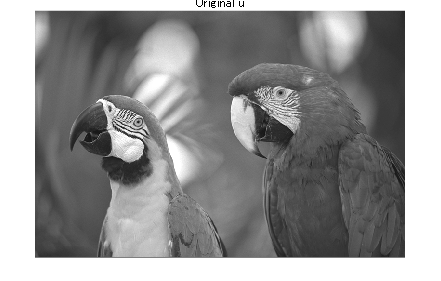

% Original image
file_uorg = './data/kodim23.png';
u = im2single(imread(file_uorg));
if size(u,3) == 3
    u = rgb2gray(u);
end
figure
imshow(u)
title('Original u')

### 観測画像

(Observed image)

以下の観測の単一画像超解像を行う．

(Let us consider the single image super resolution problem of observation))

    
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


$\mathbf{u}$ を原画像として，加法性白色ガウスノイズ$\mathbf{w}$ と低解像度観測過程$\mathbf{P}$が加わり劣化している．ここで，観測過程は低域通過フィルタとダウンサンプルからなる線形処理である．

(which originates  $\mathbf{u}$ and is contaminated by additive white Gaussian noise $\mathbf{w}$ and downscale measurement proces, where $\mathbf{P}$ is a linear process consisting of low-pass filter and downsampling.)

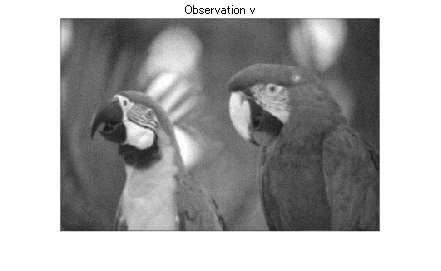

% Measurement process P
sigmah = 2;
h = fspecial('gaussian',9,sigmah);
downsample2 = @(x,m) ipermute(downsample(permute(downsample(x,m),[2 1 3]),m),[2 1 3]);
linproc = @(x) downsample2(imfilter(x,h,'conv','circ'),2);
H = fftn(h,2.^nextpow2([size(u,1) size(u,2)]));
beta = max(abs(H(:)).^2); % λmax(PP.')

% Observation
sigmaw = 5/255;
v = imnoise(linproc(u),'gaussian',0,sigmaw^2);
figure
imshow(v)
title('Observation v');

## 双三次補間

(Bicubic interpolation)

参考までに，双三次補間の結果を示す．

(For the sake of reference, the result with the bicubic interpolation is shown.)

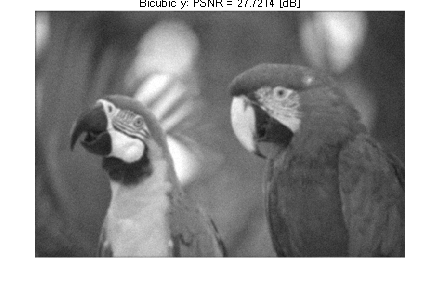

% Bicubic
y = imresize(v,2,'bicubic');
figure
imshow(y)
title(['Bicubic y: PSNR = ' num2str(psnr(u,y)) ' [dB]']);

## 単一画像超解像

(Single image super resolution)

上記の超改造問題は，冗長辞書 $\mathbf{D}$を用いて$\ell_1$-ノルム正則化崔譲二乗問題として

(The above super-resolution problem can be formulated by the  $\ell_1$-norm regularized least square problem with a redundant dictionary  $\mathbf{D}$  as)

    $\hat{\mathbf{s}}=\arg\min_\mathbf{s}\frac{1}{2}\|\mathbf{v}-\mathbf{PDs}\|_2^2+\lambda\|\mathbf{s}\|_1$.

のように定式化でき，その解は近接勾配アルゴリズムにより得られる．

(It is possible to obtain the solution by the proximal gradient algorithm)

   
$$\mathbf{s}^{(t+1)}\leftarrow\mathrm{prox}_{\gamma\lambda\|\cdot\|_1}(\mathbf{s}^{(t)}-\gamma\nabla f(\mathbf{s}^{(t)}))$$


   
$$\nabla f(\mathbf{s})=\mathbf{D}^T\mathbf{P}^T(\mathbf{PDs}-\mathbf{v})$$


  $[\mathrm{prox}_{\gamma\lambda\|\cdot\|_1}(\mathbf{s})]_i=\mathcal{T}_{\gamma\lambda}([\mathbf{s}]_i)=\mathrm{sign}([\mathbf{s}]_i)\cdot\max(|[\mathbf{s}]_i|-\gamma\lambda,0)$,

ただし，$0<\gamma<2/\beta$ であり， $\beta$ は $\nabla f$のリプシッツ定数である．

(where  $0<\gamma<2/\beta$ and $\beta$ is the Lipschitz constant of $\nabla f$.)

以下では，サンプル13-4で訓練したNSOLTとともに近接勾配法を利用して単一画像超解像を行う．

(In the following, let us perform single image super-resolution (SISR) with a proximal gradient method using the nonseparate oversampled laped transform (NSOLT) trained in Sample 13-4 as a dictionary.)

 $\mathbf{DD}^T=\mathbf{I}$ なので，(Since  $\mathbf{DD}^T=\mathbf{I}$ holds,  )

 $\beta=\lambda_\mathrm{max}(\mathbf{D}^T\mathbf{P}^T\mathbf{PD})=
(\mathbf{PD}\mathbf{D}^T\mathbf{P}^T)=
(\mathbf{P}\mathbf{P}^T)=\lambda_\mathrm{max}(\mathbf{PP}^T)=\sigma_\mathrm{max}^2(\mathbf{P})$.

である．NSOLTの設計データは "data" フォルダの下の"nsoltdictionary.mat"にある．

(The design data of NSOLT is saved in "nsoltdictionary.mat" under the folder "data".)

### NSOLT辞書の読込み

(Loading NSOLT dictionary)

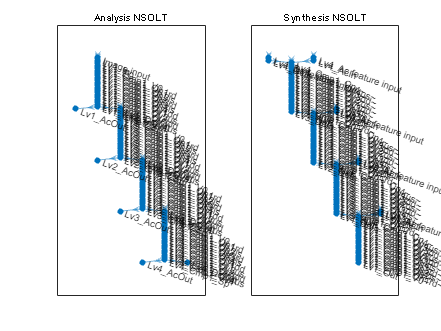

import msip.*
load ./data/nsoltdictionary_20230705164652136.mat
analysislgraph = layerGraph(analysisnet);
synthesislgraph = layerGraph(synthesisnet);

figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

### 要素画像の表示

(Show the atomic images)

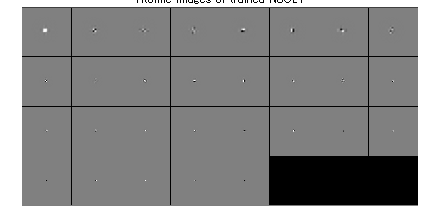

figure
atomicimshow(synthesisnet,[],2^(nLevels-1))
title('Atomic images of trained NSOLT')

import msip.*
nLevels = extractnumlevels(analysisnet);
decFactor = extractdecfactor(analysisnet);
nChannels = extractnumchannels(analysisnet);
szOrg = size(u);

% Assemble analyzer
analysislgraph4predict = analysislgraph;
analysislgraph4predict = analysislgraph4predict.replaceLayer('Image input',...
    imageInputLayer(szOrg,'Name','Image imput','Normalization','none'));
for iLayer = 1:height(analysislgraph4predict.Layers)
    layer = analysislgraph4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        analysislgraph4predict = analysislgraph4predict.replaceLayer(layer.Name,...
            regressionLayer('Name',layer.Name));
    end
end
analysisnet4predict = assembleNetwork(analysislgraph4predict);

% Assemble synthesizer
synthesislgraph4predict = synthesislgraph;
synthesislgraph4predict = synthesislgraph4predict.replaceLayer('Lv1_Out',...
    regressionLayer('Name','Lv1_Out'));
for iLayer = 1:height(synthesislgraph4predict.Layers)
    layer = synthesislgraph4predict.Layers(iLayer);
    if contains(layer.Name,'Ac feature input')
        iLv = str2double(layer.Name(3));
        sbSize = szOrg.*(decFactor.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize (sum(nChannels)-1)],'Name',layer.Name,'Normalization','none');
        synthesislgraph4predict = synthesislgraph4predict.replaceLayer(...
            layer.Name,newlayer);
    elseif contains(layer.Name,sprintf('Lv%0d_Dc feature input',nLevels))
        iLv = str2double(layer.Name(3));
        sbSize = szOrg.*(decFactor.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize 1],'Name',layer.Name,'Normalization','none');
        synthesislgraph4predict = synthesislgraph4predict.replaceLayer(...
            layer.Name,newlayer);
    end
end
synthesisnet4predict = assembleNetwork(synthesislgraph4predict);  

### 随伴関係（完全再構成）の確認

(Confirmation of the adjoint relation (perfect reconstruction))

NSOLTはパーセバルタイト性を満たすことに注意．(Note that NSOLT satisfy the Parseval tight property.)

x = rand(szOrg,'single');
[s{1:nLevels+1}] = analysisnet4predict.predict(x);
y = synthesisnet4predict.predict(s{1:nLevels+1});
display("MSE: " + num2str(mse(x,y)))

    "MSE: 2.8769e-14"



#### 観測過程の随伴作用素

(Adjoint operator of the measurement process)

% Adjoint process P.'
upsample2 = @(x,m) ipermute(upsample(permute(upsample(x,m),[2 1 3]),m),[2 1 3]);
adjproc = @(x) imfilter(upsample2(x,2),h,'corr','circ');

## 近接勾配法(ISTA)の実行

(Execution of proximal-gradient method (ISTA))

- "synthesisnet" and "analysisnet" are objects of "dlnetwork."

- "dlnetwork" takes "dlarray."

- Function "extractdata" is used for extracting ordinary array data from "dlarray."  

% Parameter settings
lambda = 0.001;
gamma = 2./(beta+1e-2);
nIters = 100;
isDcSkip = true;

% Initalization
z = zeros(szOrg,'like',u);
[coefs{1:nLevels+1}] = analysisnet4predict.predict(z);

% profile on
for itr = 1:nIters
    x = linproc(synthesisnet4predict.predict(coefs{1:nLevels+1}));
    [g{1:nLevels+1}] = analysisnet4predict.predict(adjproc(x-v));
    % Gradient descnet
    for iOutput = 1:nLevels+1
        coefs{iOutput} = coefs{iOutput}-gamma*g{iOutput};
        if ~isDcSkip || iOutput < nLevels+1 
            % ISTA for detail (w/o soft-thresholding for approximation components)
            coefs{iOutput} = wthresh(coefs{iOutput},'s',gamma*lambda);
        end
    end
end
% profile off
% profile viewer


% Reconstruction
r = synthesisnet4predict.predict(coefs{1:nLevels+1});

### 結果の表示

(Display the result)

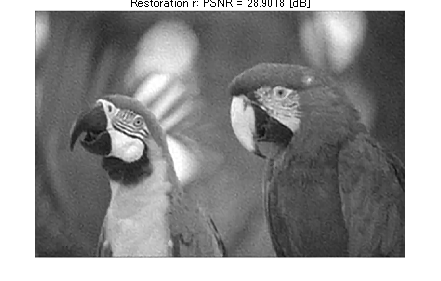

figure
imshow(r)
title(['Restoration r: PSNR = ' num2str(psnr(u,r)) ' [dB]'])

function nLevels = extractnumlevels(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expidctlayer = '^Lv\d+_E0~?$';
nLevels = 0;
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expidctlayer,'once'))
        nLevels = nLevels + 1;
    end
end
end

function decFactor = extractdecfactor(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        decFactor = layer.DecimationFactor;
    end
end
end

function nChannels = extractnumchannels(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        nChannels = layer.NumberOfChannels;
    end
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.